format longg
CP = py.importlib.import_module("CoolProp.CoolProp");

zeta_ind = 0.2;
zeta_boj_90 = 0.30;
zeta_boj_135 = zeta_boj_90 * 1.5;
zeta_boj_180 = zeta_boj_90 * 2;
zeta_buffer = 1 + 0.25;
zeta_flow = 1;
zeta_filter = 3;
zeta_skue = zeta_buffer;


zeta_total = zeta_ind + 5*zeta_boj_90 + 3*zeta_boj_135 + zeta_boj_180...
    + zeta_buffer + zeta_flow + zeta_filter + zeta_skue

zeta_total =                      10.15


**For væske**

L = 1.95 %1.95; %m

L =                       1.95


t = 0.00080; %m
d = 0.00794 - 2*t %m

d =                    0.00634


d_i = 0.008 - 2*0.0002 %m diameteren ud af kondensatoren

d_i =                     0.0076



c_i = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren

% c * d^2 = d_i^2 * c_i %countinuitetsligningen
c = d_i^2 * c_i / d^2

c =         0.0856597257765565



rho_fluid = 1186.61436781861; %kg/m^3 




nu = CP.PropsSI('V', 'H', 242310, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       0.000182597977122283


Re = c * d / nu 

Re =           2.97419867395176



% Re < 2300 dermed laminart flow


% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

lambda =            21.518401094223



Delta_p_ror = lambda * L * c^2 * rho_fluid / (d * 2)

Delta_p_ror =           28812.9893178862



Delta_p_enkelt = zeta_total * (rho_fluid * c^2)/ 2

Delta_p_enkelt =           91.4223248585915


**For gas**

c = 2.26638867101572; %m/s    
rho_vape = 31.2106794247976; %kg/m^3 



L = 6.7 %1.95%1.95 %m

L =                        6.7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'H', 390410, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       1.01936374199676e-05


Re = c * d / nu 

Re =           1760.88255202052



% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



lambda = 64/Re  % <-----------

lambda =         0.0363454109568882



Delta_p_ror = lambda * L * c^2 * rho_vape / (d * 2)

Delta_p_ror =           2464.57031579051



% Delta_p = zeta_total * (rho * c^2)/ 2


## For Fordamperen

rho1 = CP.PropsSI('D', 'Q', 0, 'P', 886810, 'R134a')%1186.61436781861; %kg/m^3 

rho1 =           1167.53140714855


c1 = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren

d1 = 0.008 - 2*0.0002

d1 =                     0.0076


d2 = 0.00952 - 2*t

d2 =                    0.00792


% c1 = 2.26638867101572; %m/s     
% rho = CP.PropsSI('D', 'H', 242310, 'P', 132700, 'R134a')%1186.61436781861; %kg/m^3 
rho_for = CP.PropsSI('D', 'T', 273.15 -20, 'P', 132700, 'R134a')%1186.61436781861; %kg/m^3 

rho_for =           6.78260275854283



c2 = c1 * rho1 * d1^2 / (d2^2 * rho_for )

c2 =           9.44880795807775



L = 6.7 %1.95%1.95 %m

L =                        6.7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'T', 273.15 -20, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       9.99947709489375e-06



K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879


% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



% lambda = 64/Re  % <-----------
lambda = 0.035

lambda =                      0.035


Re = c2 * d2 / nu

Re =           7483.84723699104



Delta_p_ror = lambda * L * c2^2 * rho_for / (d2 * 2)

Delta_p_ror =           8964.74821730824



% Delta_p = zeta_total * (rho * c^2)/ 2

## For Kondensatoren

**For væske**

L = 45 %1.95; %m

L =     45


t = 0.0002; %m
d = 0.008 - 2*t %m diameteren ud af kondensatoren

d =                     0.0076



c_fluid = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren



rho_fluid = 1186.61436781861; %kg/m^3 




nu = CP.PropsSI('V', 'H', 242310, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       0.000182597977122283


Re = c * d / nu 

Re =           94.3304749109265



% Re < 2300 dermed laminart flow


% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

lambda =          0.678465788075734



Delta_p_ror = lambda * L * c_fluid^2 * rho_fluid / (d * 2)

Delta_p_ror =           8469.59226371349


**For gas**

c_vape = 2.26638867101572; %m/s    
rho_vape = 31.2106794247976; %kg/m^3 


L = 45 %1.95%1.95 %m

L =     45


t = 0.0002; %m
d = 0.008 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                     0.0076



nu = CP.PropsSI('V', 'H', 390410, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       1.01936374199676e-05


Re = c * d / nu 

Re =           1689.73578224192



% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000394736842105263



lambda = 64/Re  % <-----------

lambda =         0.0378757440498098



Delta_p_ror = lambda * L * c_vape^2 * rho_vape / (d * 2)

Delta_p_ror =           17976.3743321259


enektl modstande


zeta_boj_90 = 0.30;

zeta_boj_180 = zeta_boj_90 * 2;



zeta_total = zeta_boj_180 * 35

zeta_total =     21



Delta_p = zeta_total * (rho_fluid * c_fluid^2)/ 2

Delta_p =            44.274628271481


Delta_p = zeta_total * (rho_vape * c_vape^2)/ 2

Delta_p =           1683.29914647824


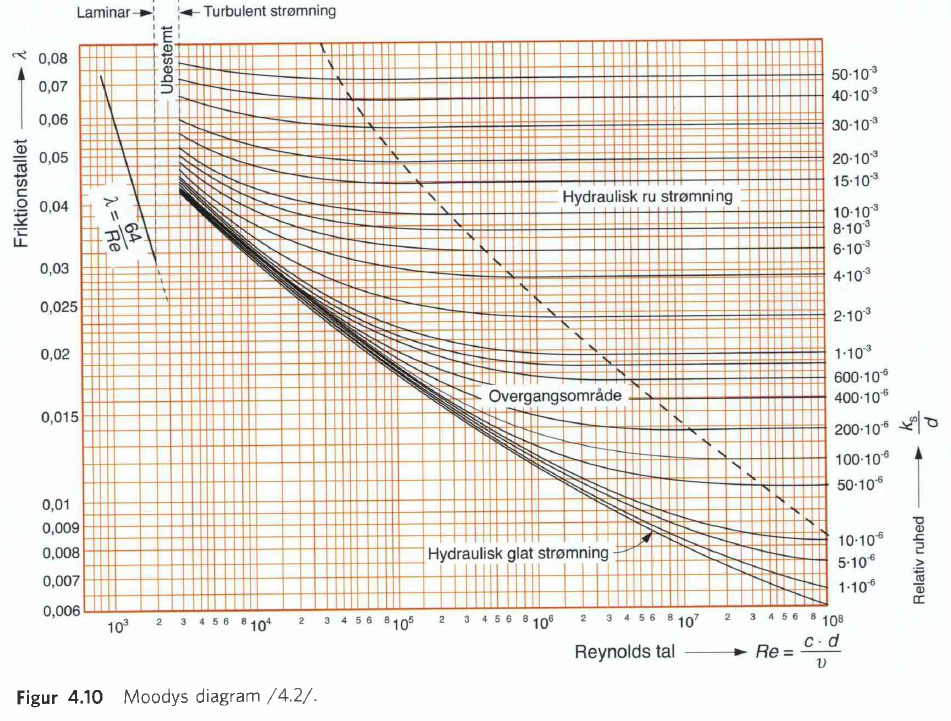

Video til coolprop

[https://www.youtube.com/watch?v=XvR10Fjph7U](https://www.youtube.com/watch?v=XvR10Fjph7U) 

For coolprop

[https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png](https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png)